# Chapter 4 Exercise 67

Identificazione di un sistema nel dominio del tempo utilizzando modelli parametrici di rumore

Identificare un modello di un sistema dinamico lineare in presenza di rumore disturbante

clear all

% define the input variables

N=5000;                                     % length of the processed data records
NTrans=500;                                 % eliminate transients in simulation (elementi che devono essere ignorati perchè fanno parte del transitorio)

Nei sistemi dinamici, i transitori sono le fasi iniziali di un'onda o un segnale prima di raggiungere uno stato stabile dopo un cambiamento o una perturbazione. Durante i transitori, il sistema può mostrare comportamenti transitori, come oscillazioni o variazioni temporanee, prima di raggiungere uno stato stazionario o di equilibrio.

L'eliminazione dei transitori viene effettuata per evitare di includere nel modello i comportamenti transitori che non rappresentano il vero comportamento stabile del sistema ed ottenere così stime più accurate dei parametri del modello e per evitare che i comportamenti transitori influenzino l'analisi dei dati.

NRep=20;                                    % number of repeated simulations

Vengono effettuate simulazioni ripetute per ottenere una valutazione più robusta e affidabile delle prestazioni del modello. L'obiettivo è valutare la variabilità dei risultati ottenuti al variare delle condizioni iniziali (cambia *u0*) o dei disturbi nel sistema (cambia *yNoise*).

## Creazione dei filtri

Vengono creati due filtri, uno di Butterworth ed uno di Chebyshev. Il filtro di Butterworth viene applicando all'ingresso (entra u ed esce u') ed è definito da *Ggen* con coef. del numeratore salvati in *bGen* e del denom. in *aGen*. In ingresso al filtro di Chebyschev ho l'ingresso filtrato, ovvero u', in uscita ho *y0*. Il filtro di Chebyshev costituisce il plant. Esso è definito da *G0* e i coef. del num. sono salvati in b0 mentre quelli del denom. in a0.

OrderG=2;                                   % order of the plant
fMax=0.4;                                   % larghezza di banda generator signal (fs=1)
[bGen,aGen]=butter(3,2*fMax);               % filtro Butterworth di ordine 3 con una frequenza di taglio di 2*fMax. I coefficienti del filtro vengono assegnati alle variabili bGen e aGen che rappresentano, rispettivamente, i coefficienti del numeratore e del denominatore del filtro. 'low' è l'impostazione predefinita se il secondo parametro è scalare. used to generate the excitation of the system (input)
[b0,a0]=cheby1(OrderG,10,2*fMax*0.9);       % plant to be estimated(viene generato il sistema G0).  filtro di Chebyshev di tipo 1 di ordine OrderG=2 con un'attenuazione di 10 dB e una frequenza di taglio di 2*fMax*0.9. I coefficienti del filtro vengono assegnati alle variabili b0 e a0.
stdNoise=0.1;                               % deviazione standard del disturbing noise

***butter***** restituisce i coefficienti della funzione di trasferimento di un filtro Butterworth passabasso digitale di ordine 3 (in questo caso), più è elevato l'ordine del filtro e maggiore è l‘attenuazione delle armoniche fuori banda, con frequenza di taglio normalizzata pari a 2*fMax (se passa-basso il filtro '' fa passare '' tutte le frequenze inferiori a questa, se passa-alto '' lascia passare '' le frequenze al di sopra di quella di taglio definita). In questo caso, quando non specificato il tipo (terzo parametro), si tratta di un filtro passa-basso.**

Un filtro Butterworth è un tipo di filtro analogico o digitale che viene utilizzato per attenuare determinate frequenze in un segnale. 

Un filtro Butterworth è caratterizzato da una risposta in frequenza "piatta" nella banda passante desiderata, il che significa che attenua le frequenze indesiderate in maniera uniforme senza presentare picchi o depressioni.

- ***cheby1***** restituisce i coefficienti della funzione di trasferimento di un filtro Chebyshev di tipo I digitale passa-basso di ordine 2 (in questo caso perchè OrderG = 2 corrisponde al numero di poli della sua funzione di trasferimento e influisce sulla pendenza della curva di attenuazione in maniera direttamente proporzionale) con attenuazione espressa in decibel pari a 10 (attenua di 10db tutti i segnali al di sopra della frequenza di taglio) e frequenza di taglio normalizzata 2*fMax*0.9**

Ci sono due tipi principali di filtri Chebyshev: i filtri Chebyshev tipo I e i filtri Chebyshev tipo II. I filtri Chebyshev tipo I presentano oscillazioni sia nella banda passante che nella banda di stop, mentre i filtri Chebyshev tipo II presentano oscillazioni solo nella banda di stop.

A differenza dei f**iltri Butterworth** che **hanno una risposta in frequenza "piatta" nella banda passante**,** i filtri Chebyshev presentano delle risonanze o oscillazioni** nella risposta in frequenza **nella banda passante**. Queste oscillazioni consentono di ottenere una maggiore pendenza di attenuazione (risposta in frequenza più selettiva) rispetto ai filtri Butterworth, ma a discapito di una risposta in frequenza meno "piatta".Il filtro di Chebyshev può raggiungere un'attenuazione più elevata rispetto a un filtro di Butterworth dello stesso ordine, ovvero per ottenere la stessa attenuazione il filtro di Chebyshev può richiedere un ordine inferiore rispetto a un filtro di Butterworth. (minore è l'ordine meno complessa è la realizzazione del filtro)

Sotto vengono mostrate le risposte in frequenza dei due filtri (ho diverse pendenze per diversi ordini):

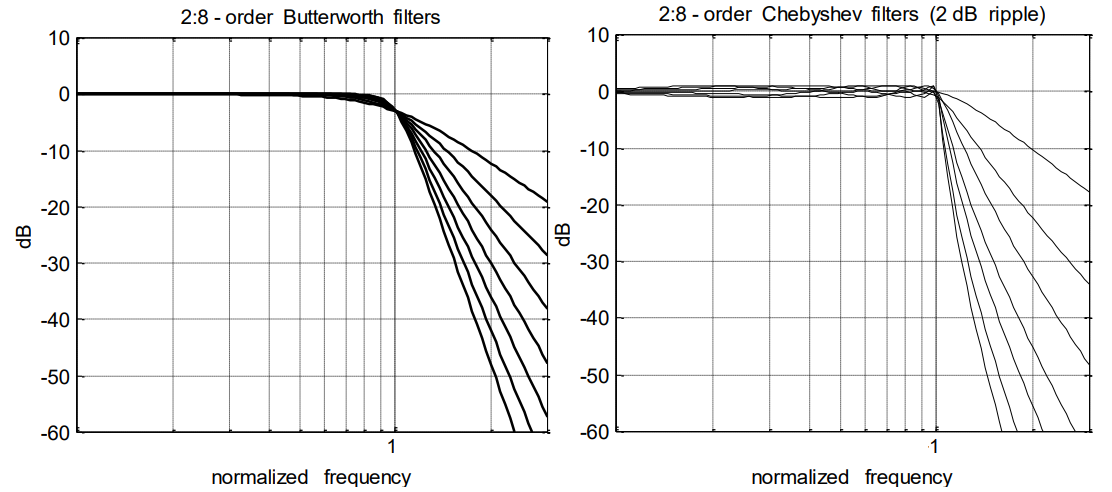

% calcolo la risposta in frequenza (equivalente ad una fdt) del filtro di chebyshev (plant) sopra menzionato

fMaxPlot=N*min(fMax*1.5,0.5);               %Calcola il valore massimo della frequenza di plotting fMaxPlot. Prende il valore minimo tra fMax*1.5 e 0.5 e lo moltiplica per N. Questo assicura che fMaxPlot sia limitato a un valore massimo di 0.5 o a fMax*1.5 a seconda di quale sia il valore più piccolo. Questo valore viene utilizzato successivamente per definire la griglia delle frequenze.
w=[0:fMaxPlot/100:fMaxPlot]/N*2*pi;         %freq grid.Crea un vettore w che rappresenta una griglia di frequenze. Va da 0 a fMaxPlot con incrementi di fMaxPlot/100 e rappresenta le frequenze normalizzate. Successivamente, il vettore viene diviso per N e moltiplicato per 2*pi per ottenere le frequenze angolari in radianti.
G0=freqz(b0,a0,w);                          %Calcola la risposta in frequenza del sistema. Prende come input i coefficienti del numeratore b0 e del denominatore a0 della funzione di trasferimento del sistema (date dal plant del filtro di Chebyshev), insieme alle frequenze angolari w. La funzione freqz() restituisce la risposta in frequenza G0 del sistema valutata sui punti della griglia delle frequenze.

in *G0* ho la risposta in frequenza valutata alle frequenze normalizzate specificate dal parametro *"w". *Ho 101 valori in* G0, *uno per ogni* 'w'*

La risposta in frequenza è una caratteristica di un sistema che descrive come il sistema reagisce a segnali in ingresso a diverse frequenze. Rappresenta la relazione tra l'ampiezza e la fase del segnale in uscita rispetto al segnale in ingresso al variare della frequenza.

Nel contesto dei sistemi lineari e tempo invariante (LTI), la risposta in frequenza è spesso rappresentata mediante una funzione complessa chiamata funzione di trasferimento. La funzione di trasferimento descrive il comportamento del sistema per ogni frequenza e specifica l'attenuazione o l'amplificazione del segnale in ingresso e la sua fase rispetto al segnale in uscita.

## Parametri per 3 diversi filtri: ARX, BOX-JENKINS, OUTPUT-ERROR

Vengono definiti 3 diversi modelli di filtri che verranno applicati ad un rumore sull'uscita.

Avrò un rumore sull'uscita. Questo rumore viene filtrato da un filtro/blocco con funzione W(z). Tale funziona cambierà all'interno di un *ciclo for (con indice r) *ed avrà caratteristiche conformi al tipo di modello che si vuole simulare:

ARX, OE oppure Box-Jenkins

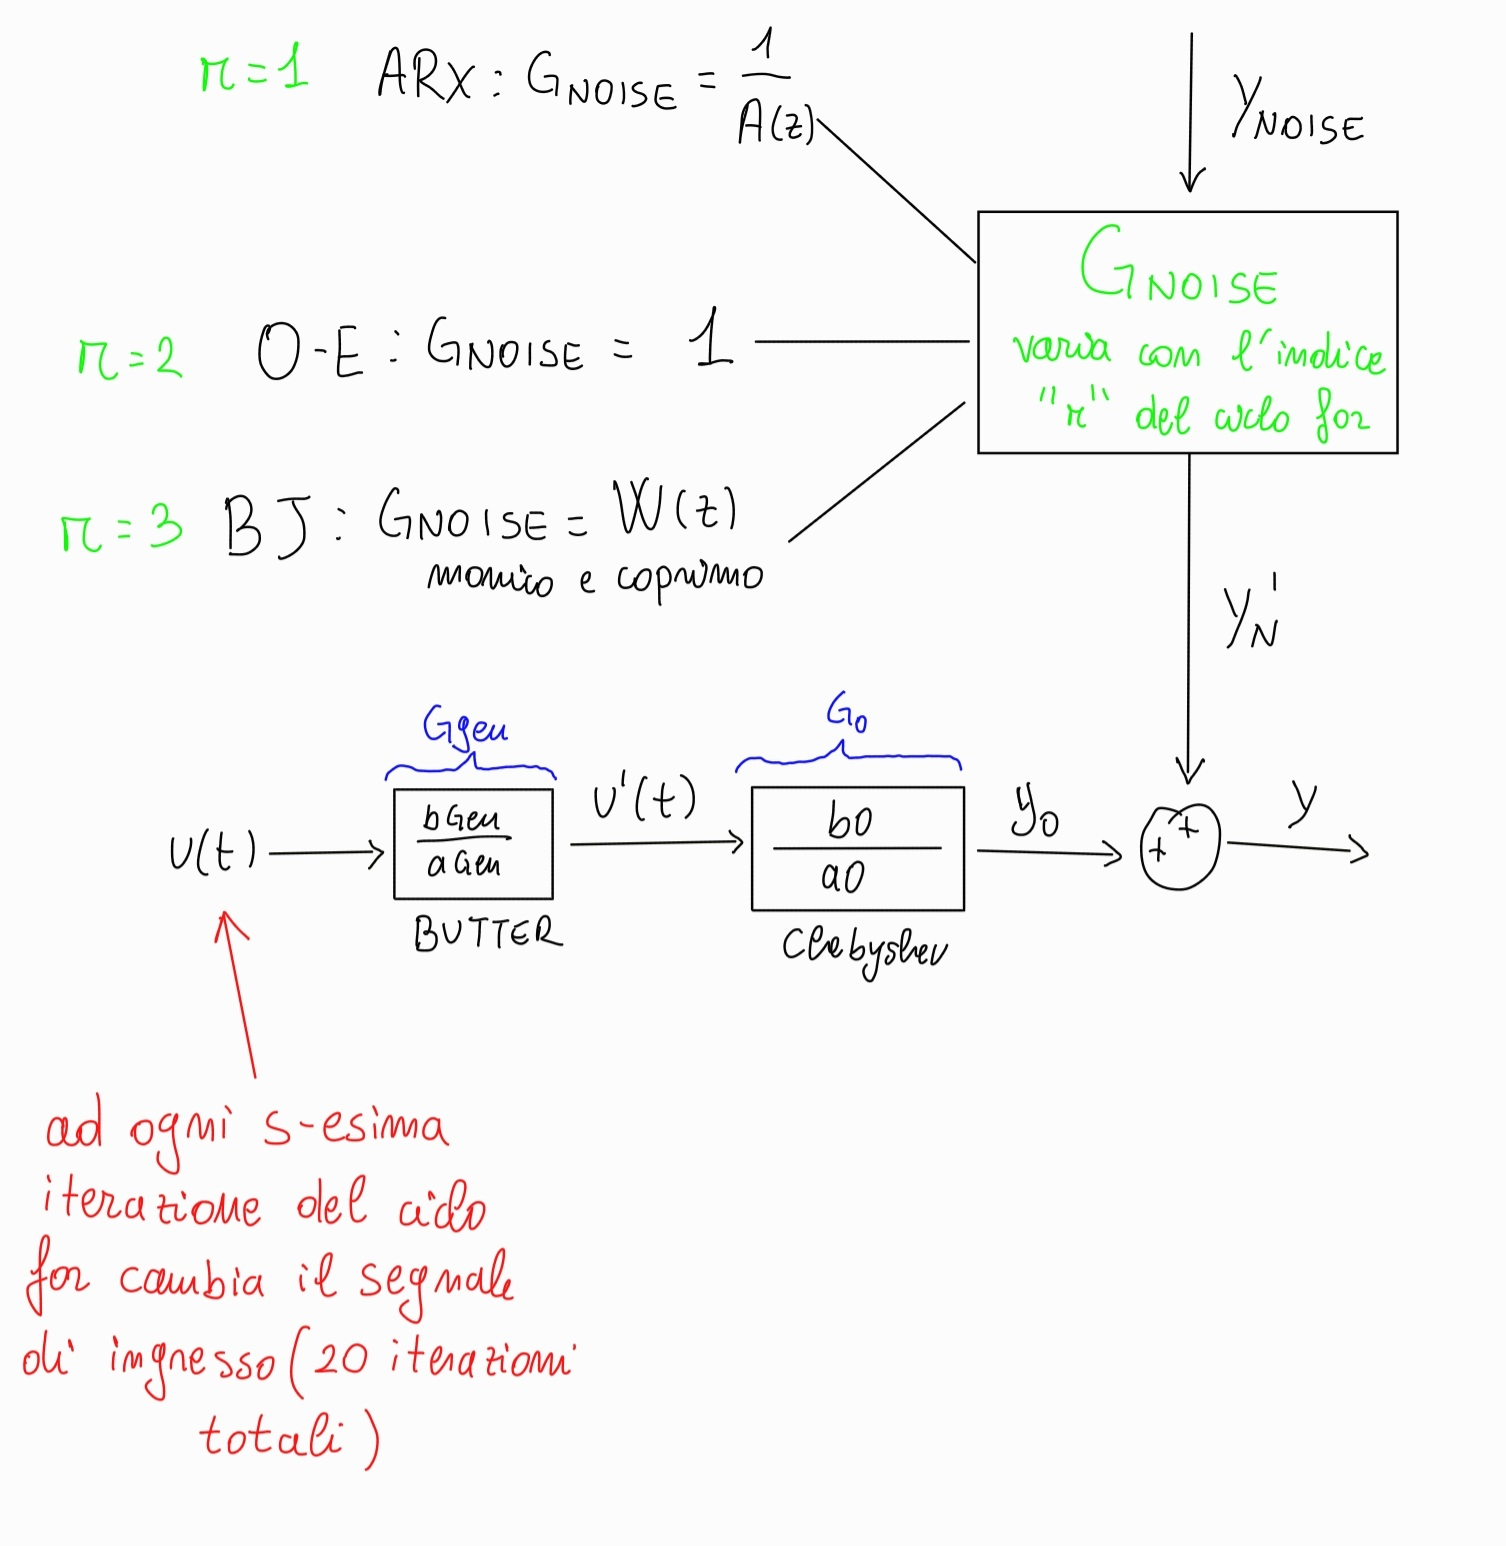

% per il modello ARX ho W(z) = 1/A(z)  →  coef. del num. (bNoise) pari ad 1
% coef. del denom. (aNoise) ≠ 0

bNoise{1}=1;                               
aNoise{1}=a0;                               %coefficiente del filitro di Chebyshev visto sopra
OrderNoise(1)=OrderG;                       % ordine pari 2




% per il modello OE ho W(z) = 1  →  coef. del num. (bNoise) e del denom. (aNoise) pari ad 1
% avrò quindi un rumore bianco puro dato che il filtro lineare è unitario

bNoise{2}=1;                                
aNoise{2}=1;                               
OrderNoise(2)=0;




% per il modello BJ ho W(z) deve avere polinomi monici al numeratore (bNoise) e denominatore (aNoise) e anche dello stesso grado
% e inoltre deve essere asintoticamente stabile

OrderNoise(3)=2;                           
[b,a]=butter(OrderNoise(3),2*fMax/3,'low');     % noise model 'low' specifica un filtro passa-basso con frequenza di taglio 2*fMax/3.
bNoise{3}=b;                                    % NON È MONICO!!!!!!!!!!!!!!!!!!!!!!!!!!
qwerty = bNoise{3};     
aNoise{3}=a; 
qwerty2 = aNoise{3};
[A,B,C,D] = tf2ss(bNoise{3},aNoise{3});
eig(A)                                          % POLI ALL'INTERNO DEL CERCHIO UNITARIO  →  È ASINTOTICAMENTE STABILE

ans =    0.4386 + 0.3445i
   0.4386 - 0.3445i


## Simulations: generation and estimation of the data per ciascun modello di rumore

- Stimare i parametri del modello del sistema e del rumore per ciascuna delle tre distorsioni, utilizzando il modello ARX, OE e BJ.

- Ripetere ciò 20 volte(NRep) e calcolare il valore RMS(Root Mean Square: radice quadrata della media dei quadrati) dell'errore complesso |G0(jw) - G(jw)| come funzione della frequenza.

% in questo primo ciclo for si scorrono i vari filtri definiti prima  e se
% ne calcola la risposta in frequenza e l'SNR con la fdt del filtro
% generatore (Ggen: Butterworth applicato sull'ingresso) 

for r=1:3                                   
     Ggen=abs(freqz(bGen,aGen,w));                           % con la funzione "freqz()" calcola la risposta in frequenza del filtro generatore (quello di Butterworth sull'ingresso) utilizzando i coefficienti del numeratore (bGen) e del denominatore (aGen). Con la funzione abs() si ottiene il valore assoluto della risposta in frequenza così da avere solo i valori di ampiezza.
     Gnoise=stdNoise*abs(freqz(bNoise{r},aNoise{r},w));      % Come sopra calcoliamo la risposta in frequenza del filtro del rumore (Gnoise) utilizzando li coefficienti del numeratore (bNoise{r}) e del denominatore (aNoise{r}) del filtro del rumore. Inoltre, il valore di stdNoise (deviazione standard del rumore) viene moltiplicato per la risposta in frequenza per scalare adeguatamente il rumore.
     SNR{r}=db(Ggen./Gnoise);                                % Calcoliamo il rapporto segnale rumore come il logaritmo in base 10 del rapporto tra la risposta in frequenza del filtro generatore e la risposta in frequenza del filtro del rumore. La funzione "db" converte il valore dell'ampiezza in decibel.
  

ans =      1    20


ans =      1    19


ans =      1    18


ans =      1    17


ans =      1    16


ans =      1    15


ans =      1    14


ans =      1    13


ans =      1    12


ans =      1    11


ans =      1    10


ans =      1     9


ans =      1     8


ans =      1     7


ans =      1     6


ans =      1     5


ans =      1     4


ans =      1     3


ans =      1     2


ans =      1     1


ans =      2    20


ans =      2    19


ans =      2    18


ans =      2    17


ans =      2    16


ans =      2    15


ans =      2    14


ans =      2    13


ans =      2    12


ans =      2    11


ans =      2    10


ans =      2     9


ans =      2     8


ans =      2     7


ans =      2     6


ans =      2     5


ans =      2     4


ans =      2     3


ans =      2     2


ans =      2     1


ans =      3    20


ans =      3    19


ans =      3    18


ans =      3    17


ans =      3    16


ans =      3    15


ans = 1×2
     3    14


ans = 1×2
     3    13


ans = 1×2
     3    12


ans = 1×2
     3    11


ans = 1×2
     3    10


ans = 1×2
     3     9


ans = 1×2
     3     8


ans = 1×2
     3     7


ans = 1×2
     3     6


ans = 1×2
     3     5


ans = 1×2
     3     4


ans = 1×2
     3     3


ans = 1×2
     3     2


ans = 1×2
     3     1


Abbiamo calcolato il rapporto segnale-rumore (SNR) in decibel per ogni punto della griglia delle frequenze, questo può fornire informazioni sulla qualità del segnale rispetto al rumore in diverse frequenze.

Fare il rapporto tra *Ggen* e *Gnoise* equivale a farlo tra u(t) e yNoise in quanto sono uguali, entrambi sono dati da '*randn(N+Ntrans,1)*'. I due segnali uguali (a meno del risultato casuale di *randn*) entrano in due filitri differenti  →  mi basta vedere come e di quanto differiscono i due filtri.

Effettuare ripetizioni multiple consente di osservare la variabilità nel comportamento del sistema a causa del rumore e di calcolare le statistiche delle prestazioni, come l'errore quadratico medio (RMS) o la deviazione standard, per valutare la precisione del modello o identificare le caratteristiche del sistema in diverse condizioni.

     % in questo secondo ciclo for vengono fatte Nrep=20 ripetizioni nelle
     % quali varia il rumore sull'uscita (yNoise per via della funzione 'randn')
     % e l'ingresso u0 (per via della funz. 'randn') e di conseguenza anche l'uscita
     
     for s=NRep:-1:1                         
        [r,s]                                                   % semplice visualizzazione dei contatori dei due cicli for
        u0=randn(N+NTrans,1);                                   % Genera un vettore casuale u0 di lunghezza N+NTrans utilizzando la distribuzione normale (gaussiana) 
        u0=filter(bGen,aGen,u0);                                % filtered random input. Filtra quello della riga precedentemente con il filtro di Butterworth. Questo genera un segnale di input filtrato che viene assegnato a u0.
        y0=filter(b0,a0,u0);                                    % exact output.  Filtra il segnale uscente da Butterworth con il filtro di Chebyshev per ottenere il segnale di output esatto y0 senza rumore.
        yNoise=filter(bNoise{r},aNoise{r},randn(N+NTrans,1));   % Genera un vettore casuale di rumore di lunghezza N+NTrans utilizzando la distribuzione normale (gaussiana) e lo filtra con uno dei filtri creati precedentemente (in base alla r-esima iterazione).
        yNoise=stdNoise*yNoise;                                 % Moltiplica il rumore filtrato yNoise per stdNoise, che rappresenta la deviazione standard del rumore. Questo scala il rumore in base alla deviazione standard specificata.
        y=y0+yNoise;                                            %  Aggiunge il rumore scalato yNoise al segnale di output esatto y0 per ottenere il segnale di output finale y.
        u0(1:NTrans)=[];                                        % Elimina i transitori delle simulazioni, rimuovendo i primi NTrans campioni dai segnali di input u0 e output y. Questo viene fatto per eliminare gli effetti transitori iniziali causati dai filtri.
        y(1:NTrans)=[];

## three different estimators

Viene effettuata la stima dei parametri del modello dell'intero sistema, dando come argomenti, allo stimatore, l'ingresso filtrato dal filtro di Butterworth e l'uscita finale comprendente il rumore.

Si cerca di stimare il sistema con gli stessi 3 modelli utilizzati per definire il filtro sul rumore sull'uscita, ovvero ARX, OE e BJ

        Moe = oe([y u0],[OrderG+1 OrderG 0],'maxiter',1000,'tol',1e-6,'lim',0);     % output error method

**È un output error (è un particolare modello delal famiglia Box-Jenkins)  →  l'errore si somma all'uscita. Si assume W(z) = 1 per questi modelli  →  assenza di filtro**

L'algoritmo OE utilizza un approccio di minimizzazione dell'errore tra il modello stimato e i dati sperimentali. Cerca di minimizzare la differenza tra il segnale di output stimato dal modello e il segnale di output reale (dato sperimentale). Utilizzando i dati di input e output disponibili, l'algoritmo stima i parametri del modello che meglio approssimano i dati sperimentali.

- OrderG+1=nb, OrderG=nf, e 0=nk rappresentano gli ordini dei polinomi per stimare il modello OE, rappresentano rispettivamente l'ordine del numeratore del modello, l'ordine del denominatore del modello e l'ordine del ritardo (input delay) del modello. 

- `'maxiter',1000`: specifica il numero massimo di iterazioni consentite durante il processo di stima dei parametri. Nel caso in cui l'algoritmo non converga entro il numero massimo di iterazioni, la stima viene interrotta.

- `'tol',1e-6`: (opzionale) specifica la tolleranza di convergenza per il processo di stima dei parametri. Se la differenza tra i parametri stimati nelle iterazioni successive è inferiore a questa tolleranza, l'algoritmo viene considerato convergente e la stima viene interrotta.

- `'lim',0`: (opzionale) specifica il limite inferiore per i parametri stimati. In questo caso, viene impostato a 0, il che significa che non ci sono limiti inferiori imposti per i parametri stimati.

         Marx = arx([y u0],[OrderG OrderG+1 0],'tol',1e-6,'lim',0);                  % ARX-mehtod

**I modelli ARX (AutoRegressive eXogenous Models) sono modelli a due gradi di libertà (coincide con il numero di polinomi**

**da cui esso è caratterizzato, infatti ho due polinomi: A(z) e B(z); B(z)/A(z) sull'ingrezzo e 1/A(z) sull'errore )**

**che prevedono un’uscita costituita dalla somma di tre componenti:**

**• un contributo autoregressivo (AR) sulla uscita, infatti moltiplica 'y' (un segnale autoregressivo è un segnale i cui campioni sono calcolati come combinazione lineare dei campioni precedenti dello stesso segnale, in altre parole l’autoregressione su un dato campione è in sostanza una media pesata dei campioni precedenti);**

**• il contributo puro della variabile errore;**

**• un contributo esogeno (X) in media mobile (ovvero il contriubuto significativo dell'input sull'output; infatti moltiplica 'u')**

- `[OrderG OrderG+1 0]` specifica gli ordini dei polinomi per l'ARX. In particolare, `OrderG=na` rappresenta l'ordine dell'AR (ritardi dell'uscita), ovvero del polinomio A(z), `OrderG+1=nb` rappresenta l'ordine degli ingressi esogeni,ovvero del polinomio B(z) e `0=nk` rappresenta l'ordine del rumore residuo, ovvero il ritardo input-output, noto anche come ritardo di trasporto. Essendo nk=0  →  non ho zeri iniziali nel polinomio B(z). Tutti questi ordini devono avere valori interi non negativi

- `'tol',1e-6,'lim',0` sono opzioni aggiuntive che stabiliscono una tolleranza di 1e-6 per la convergenza e limitano l'uso di memoria per la stima dei parametri.

Mbj= bj([y u0],[OrderG+1 OrderNoise(r) OrderNoise(r) OrderG 0],'maxiter',1000,'tol',1e-6,'lim',0); % Box-Jenkins method

**Il modello di Box-Jenkins ha una struttura del tipo y(t) = [B(z)/F(z)]*u(t−nk)+[C(z)/D(z)]*e(t), quindi si ha che:**

- `OrderG+1 = nb  →  ordine del polinomio B(z) + 1???????????????`

- `OrderNoise(r) = nc  →  ordine del polinomio C(z)`

- `OrderNoise(r) = nd  →  ordine del polinomio D(z)`

- `OrderG = nf  →  ordine del polinomio F(z)`

- `0 = nk  →  input delay`

## extract results   

Viene calcolata la risposta in frequenza di ogni modello stimato ad ogni ripetizione (20 in totale) e ciascuna di queste viene salvata nella relativa matrice. Si Calcola poi l'errore tra la risposta in frequenza del modello stimato e il plant (definito dal filtro di Chebyshev *G0*) il cui ingresso, ricordiamo, è un segnale casuale filtrato dal filtro di Butterworth e l'uscita è la *y0* ( SENZA IL CONTRIBUTO DEL RUMORE)

I valori vengono salvati nelle s-esime colonne delle rispettive matrici. Ho 20 colonne perchè viene ripetuto 20 volte e ad ogni ripetizione (da 1 a 20), ricordiamo, variano i segnali casuali di ingresso u0 e di rumore yNoise.

Quindi ho questo doppio ciclo for concatenato, quello più esterno va da 1 a 3 e cambia il tipo di filtro che viene applicato a *yNoise*, il secondo, per ciascun filtro, vengono fatti 20 esperimenti (mantenendo il filtro invariato) dove cambiano l'ingresso u0 e il segnale di rumore sull'uscita *yNoise*

    % Box Jenkins processing
    [b,a]=tfdata(Mbj,'v');                  % la funzione "tfdata" estrae sotto forma di vettori ('v') i coefficienti del modello stimato. In "b" vengono inseriti i coefficienti del numeratore, in "a" quelli del denom.
    G=freqz(b,a,w);                         % calcola la risposta in frequenza del modello Box-Jenkins stimato
    Gbj(:,s)=G;                             % viene salvata la risposta in freq. calcolata precedentemente nella matrice Gbj nella colonna 's' (colonna che assume il valore in base al contatore del ciclo for).
    ebj(:,s)=abs(G0-G);                     % complex error tra la risposta in frequenza esatta G0 e la risposta in frequenza stimata G del modello nella simulazione corrente. ESSENDOCI 'abs'  →  viene effettuata una differenza di ampiezza.

    % OE processing
    [b,a]=tfdata(Moe,'v');                 % I coefficienti del numeratore e denom. assegnati rispettivamente a "b" ed "a" rappresentano la funzione di trasferimento del modello Output-Error stimato.        
    G=freqz(b,a,w);                        
    Goe(:,s)=G;                            % Salvando G nella colonna "s" vengono memorizzate le risposte in frequenza di tutte le simulazioni.
    eoe(:,s)=abs(G0-G);                   
 
    
    % ARX processing
    [b,a]=tfdata(Marx,'v');
    G=freqz(b,a,w);                        % Ho 101 righe perchè 'w' è di 101 elementi
    Garx(:,s)=G;
    earx(:,s)=abs(G0-G);
    
    end  % end loop over the repetitions
   

G_BJ = 1×1 cell array
    {101×20 double}


G_OE = 1×1 cell array
    {101×20 double}


G_ARX = 1×1 cell array
    {101×20 double}


G_BJ = 1×2 cell array
    {101×20 double}    {101×20 double}


G_OE = 1×2 cell array
    {101×20 double}    {101×20 double}


G_ARX = 1×2 cell array
    {101×20 double}    {101×20 double}


G_BJ = 1×3 cell array
    {101×20 double}    {101×20 double}    {101×20 double}


G_OE = 1×3 cell array
    {101×20 double}    {101×20 double}    {101×20 double}


G_ARX = 1×3 cell array
    {101×20 double}    {101×20 double}    {101×20 double}


Alla fine del *ciclo for*, vengono ottenuti gli errori per i modelli stimati utilizzando i tre diversi metodi (Box-Jenkins, OE, ARX) in tutte le simulazioni. Questi risultati possono essere utilizzati per analizzare le prestazioni dei modelli stimati e confrontarli con la risposta in frequenza esatta *G0*.

    %Calculate mean square error
    Ebj{r}=sqrt(mean(ebj.^2,2));        % Viene calcolato l'errore quadratico medio ricavando prima la media dei quadrati dei valori del "complex error" calcolato precedentemente, successivamente si calcola la radice quadrata
    Eoe{r}=sqrt(mean(eoe.^2,2));        % il secondo parametro = 2 di mean(...,2) indica che stiamo calcolando la media dei vaolori sulle righe; essendo il "complex error" una matrice
    Earx{r}=sqrt(mean(earx.^2,2));
end


## plot the results

Viene creato un grafico per ciascun filtro di rumore (r) che viene applicato al rumore sull'uscita, che mostra l'ampiezza in decibel dell'FRF (Frequency Response Function) stimata rispetto all'FRF esatta, l'ampiezza in decibel del segnale-rumore e l'ampiezza in decibel degli errori quadratici medi.

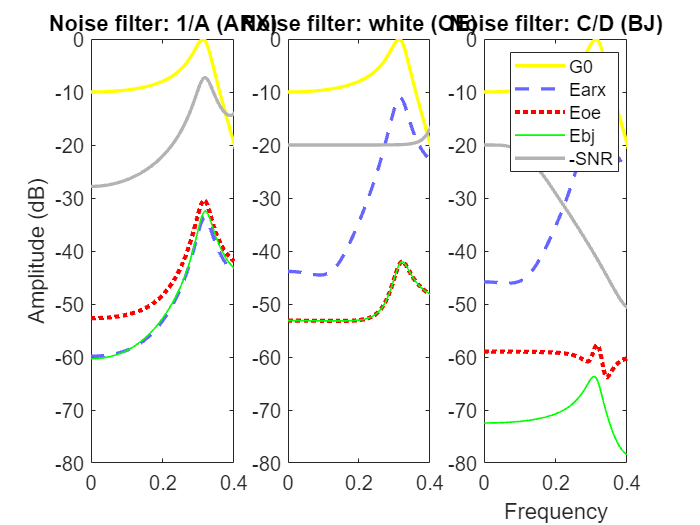

FigNum=13;
figure(FigNum)
clf

counter=0;
f=w/2/pi;                                    % frequencies for plot: valori sull'asse x

% Nomi dei grafici
Noise{1}='1/A (ARX)'; 
Noise{2}='white (OE)';
Noise{3}='C/D (BJ)';
for r=1:3   % plot di ciascun modello: ARX, OE e BJ
        counter=counter+1;
        subplot(1,3,counter)
        plot(f,db(G0),'y',f,db(Earx{r}),'b',f,db(Eoe{r}),'r',f,db(Ebj{r}),'g',f,-SNR{r},'k')    %plot della risposta in frequenza esatta (G0), l'errore delle stime con modello ARX (Earx), con modello OE (Eoe) e con modello BJ (Ebj) e il rapporto segnale-rumore (SNR).
        axis([0 fMax -80 0])                                                                    % l'asse x delle frequenze va da 0 a fMax = 0.4, l'asse y delle ampiezze da -80 a 0
        if r==1;
            ylabel('Amplitude (dB)');
        end
        title(['Noise filter: ' Noise{r}])
        DG_SetFontSize(12,FigNum,r)
end
xlabel('Frequency');
legend('G0','Earx','Eoe','Ebj','-SNR')
counter=0;   % set colors of the figures
for r=1:3   % loop over the noise filters
counter=counter+1;
        DG_SetTraceWidth(2,'*',FigNum,counter)
        DG_SetTraceTint(60,'*',FigNum,counter)
        DG_SetTraceTint(100,1,FigNum,counter)    % G0
        DG_SetTraceStyle('--',2,FigNum,counter)  % arx model
        DG_SetTraceWidth(2,1,FigNum,counter)
        DG_SetTraceStyle(':',3,FigNum,counter)  % oe model
        DG_SetTraceTint(100,3,FigNum,counter)

        DG_SetTraceWidth(2.5,3,FigNum,counter)
        DG_SetTraceWidth(1,4,FigNum,counter)   % bj
        DG_SetTraceTint(100,4,FigNum,counter)
        DG_SetTraceTint(30,5,FigNum,counter)
end

il comando "`db"` viene utilizzato per convertire le ampiezze delle risposte in frequenza stimata e dell'errore in decibel, in modo da rappresentarle su una scala logaritmica. Ciò aiuta a visualizzare e confrontare facilmente le differenze di ampiezza tra la risposta in frequenza esatta e la risposta in frequenza stimata, nonché l'errore associato.

**L'analisi dei grafici consente di valutare le prestazioni dei modelli stimati utilizzando i diversi metodi di identificazione e confrontarli con la risposta in frequenza esatta. L'obiettivo è ottenere modelli che si avvicinino il più possibile alla risposta in frequenza reale, minimizzando l'errore tra la risposta in frequenza stimata e quella esatta (G0) e massimizzando il rapporto segnale-rumore; quindi quanto più si trova in basso, rispetto l'asse y, la curva E_i tanto più l'errore è minore. **

**L'SNR є[0; +ꝏ] e quanto più è elevato tanto più il segnale è preponderante rispetto al rumore. Per poterlo rappresentare sulla nostra scala, abbiamo utilizzato -SNR e quindi, nel nostro caso, tanto più la curva grigia dell'SNR si trova in basso, sull'asse y, tanto più il rapporto segnale rumore è alto (buon risultato) e ciò vuol dire che ho un'attenuazione maggiore del rumore**

- Ogni modello è ottimale se corrisponde alla vera struttura del modello di rumore sull'uscita (comprendendo il filtro), portando alle seguenti coppie ottimali: ARX-ARX; OE-OE; BJ-BJ (ovvero, se si usa un filtro sul rumore sull'uscita che rispecchia le caratteristiche del modello ARX, la stima col modello ARX è la più efficiente; idem per gli altri modelli). Tuttavia, si può anche notare che l'utilizzo del modello BJ fornisce un risultato molto vicino a quello del modello ARX e del modello OE per il rumore ARX e il rumore OE, rispettivamente.

- Quindi il modello BJ potrebbe essere selezionato come strumento generale. Tuttavia richiede in media (molto) più tempo di calcolo. Ciò è dovuto al fatto che devono essere identificati 4 polinomi

Risposta in Frequenza Esatta (G0): Il grafico rappresenta la risposta in frequenza esatta del sistema, senza considerare il disturbo. È rappresentato dalla curva gialla nel grafico.

Errore della Risposta in Frequenza (earx, eoe, ebj): I grafici rappresentano l'errore tra la risposta in frequenza esatta (G0) e le stime ottenute utilizzando i diversi metodi. L'errore è calcolato come la differenza in ampiezza tra la risposta in frequenza esatta e la stima. Maggiore è l'errore, maggiore è la discrepanza tra la stima e la risposta esatta.